clear()

syms t f_1 f_2 t_1 t_2 real
assume(t_1 < t_2)
assume(t >= t_1)
assume(t <= t_2)
assume(f_1 >= 0)
assume(f_2 >= 0)

linFMSymFcn = f_1 + (f_2 - f_1) / (t_2 - t_1) * (t - t_1)

$$linFMSymFcn = f_{1}+\frac{\left(f_{1}-f_{2}\right)\,\left(t-t_{1}\right)}{t_{1}-t_{2}}$$

logFMSymFcn = f_1 * exp((log(f_2) - log(f_1)) / (t_2 - t_1) * (t - t_1))

$$logFMSymFcn = f_{1}\,{\mathrm{e}}^{\frac{\left(\log\left(f_{1}\right)-\log\left(f_{2}\right)\right)\,\left(t-t_{1}\right)}{t_{1}-t_{2}}}$$

sinFMSymFcn = f_1 + (f_2 - f_1) ...
    * ((sin((2 * pi * (t - t_1) / 2 / (t_2 - t_1)) ...
        - (pi / 2)) / 2) + (1 / 2))

$$sinFMSymFcn = f_{1}+\left(f_{1}-f_{2}\right)\,\left(\frac{\sin\left(\frac{\pi }{2}+\frac{\pi \,\left(t-t_{1}\right)}{t_{1}-t_{2}}\right)}{2}-\frac{1}{2}\right)$$

sinLogFMSymFcn = f_1 * exp((log(f_2) - log(f_1)) ...
                        * ((sin((2 * pi * t / 2 / (t_2 - t_1)) ...
                           - (pi / 2)) / 2) + (1 / 2)))

$$sinLogFMSymFcn = f_{1}\,{\mathrm{e}}^{\left(\log\left(f_{1}\right)-\log\left(f_{2}\right)\right)\,\left(\frac{\sin\left(\frac{\pi }{2}+\frac{\pi \,t}{t_{1}-t_{2}}\right)}{2}-\frac{1}{2}\right)}$$

t1 = 10

t1 = 10

t2 = 20

t2 = 20

testT = linspace(t1, t2, 10000)

testT =    10.0000   10.0010   10.0020   10.0030   10.0040   10.0050   10.0060   10.0070   10.0080   10.0090   10.0100   10.0110   10.0120   10.0130   10.0140   10.0150   10.0160   10.0170   10.0180   10.0190   10.0200   10.0210   10.0220   10.0230   10.0240   10.0250   10.0260   10.0270   10.0280   10.0290   10.0300   10.0310   10.0320   10.0330   10.0340   10.0350   10.0360   10.0370   10.0380   10.0390   10.0400   10.0410   10.0420   10.0430   10.0440   10.0450   10.0460   10.0470   10.0480   10.0490


f1 = 0.1

f1 = 0.1000

f2 = 50

f2 = 50


subArgs = {[t_1, t_2, f_1, f_2], [t1, t2, f1, f2]}

subArgs = 1×2 cell array
    {[t_1    t_2    f_1    f_2]}    {[10 20 0.1000 50]}


sym2func = @(sym) matlabFunction(subs(sym, subArgs{:}))

sym2func = function_handle with value:
    @(sym)matlabFunction(subs(sym,subArgs{:}))



linRampFcn = sym2func(linFMSymFcn)

linRampFcn = function_handle with value:
    @(t)t.*(4.99e+2./1.0e+2)-2.49e+2./5.0


logRampFcn = sym2func(logFMSymFcn)

logRampFcn = function_handle with value:
    @(t)exp(((log(1.0e+1)+log(5.0e+1)).*(t-1.0e+1))./1.0e+1)./1.0e+1


sinRampFcn = sym2func(sinFMSymFcn)

sinRampFcn = function_handle with value:
    @(t)sin(pi./2.0-(pi.*(t-1.0e+1))./1.0e+1).*(-4.99e+2./2.0e+1)+5.01e+2./2.0e+1


sinLogRampFcn = sym2func(sinLogFMSymFcn)

sinLogRampFcn = function_handle with value:
    @(t)exp(-(log(1.0e+1)+log(5.0e+1)).*(sin(pi./2.0-(t.*pi)./1.0e+1)./2.0-1.0./2.0))./1.0e+1


sinLogRampFcn = @(x) sinLogRampFcn(x - t1);

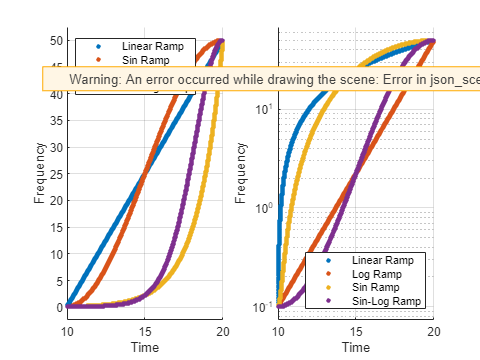

figure()
subplot(1, 2, 1);
plot(testT, linRampFcn(testT), ...
    '.', DisplayName='Linear Ramp', MarkerSize=10);
hold on
plot(testT, sinRampFcn(testT), ...
    '.', DisplayName='Sin Ramp', MarkerSize=10);
plot(testT, logRampFcn(testT), ...
    '.', DisplayName='Log Ramp', MarkerSize=10);
plot(testT, sinLogRampFcn(testT), ...
    '.', DisplayName='Sin-Log Ramp', MarkerSize=10);
xlabel('Time');
ylabel('Frequency');
ylim([f1, f2] + ([-1, 1] * (f2 - f1) * 0.05));
legend(Location='northwest');
grid on
box off

ax = subplot(1, 2, 2);
plot(testT, linRampFcn(testT), ...
    '.', DisplayName='Linear Ramp', MarkerSize=10);
hold on
plot(testT, logRampFcn(testT), ...
    '.', DisplayName='Log Ramp', MarkerSize=10);
plot(testT, sinRampFcn(testT), ...
    '.', DisplayName='Sin Ramp', MarkerSize=10);
plot(testT, sinLogRampFcn(testT), ...
    '.', DisplayName='Sin-Log Ramp', MarkerSize=10);
xlabel('Time');
ylabel('Frequency');
ylim(exp(log([f1, f2]) + ([-1, 1] * (log(f2) - log(f1)) * 0.05)));
legend(Location='southeast');
ax.YScale = 'log';
grid on
box off

freq2phase = @(symFcn, x) 2 * pi * int(symFcn, x)

freq2phase = function_handle with value:
    @(symFcn,x)2*pi*int(symFcn,x)


applyConstant = @(symFcn, x, x1) symFcn - (subs(symFcn, x, x1))

applyConstant = function_handle with value:
    @(symFcn,x,x1)symFcn-(subs(symFcn,x,x1))



linFMPhaseSymFcnUnadj = freq2phase(linFMSymFcn, t);
linFMPhaseSymFcn = applyConstant(linFMPhaseSymFcnUnadj, t, t1)

$$linFMPhaseSymFcn = 2\,\pi \,\left(f_{1}\,t+\frac{\left(f_{1}-f_{2}\right)\,{\left(t-t_{1}\right)}^{2}}{2\,\left(t_{1}-t_{2}\right)}\right)-2\,\pi \,\left(10\,f_{1}+\frac{\left(f_{1}-f_{2}\right)\,{\left(t_{1}-10\right)}^{2}}{2\,\left(t_{1}-t_{2}\right)}\right)$$


logFMPhaseSymFcnUnadj = freq2phase(logFMSymFcn, t)

$$logFMPhaseSymFcnUnadj = \frac{2\,\pi \,f_{1}\,{\left(\frac{f_{1}}{f_{2}}\right)}^{\frac{t-t_{1}}{t_{1}-t_{2}}}\,\left(t_{1}-t_{2}\right)}{\log\left(\frac{f_{1}}{f_{2}}\right)}$$

logFMPhaseSymFcn = applyConstant(logFMPhaseSymFcnUnadj, t, t1)

$$logFMPhaseSymFcn = \frac{2\,\pi \,f_{1}\,{\left(\frac{f_{1}}{f_{2}}\right)}^{\frac{t-t_{1}}{t_{1}-t_{2}}}\,\left(t_{1}-t_{2}\right)}{\log\left(\frac{f_{1}}{f_{2}}\right)}-\frac{2\,\pi \,f_{1}\,\left(t_{1}-t_{2}\right)}{\log\left(\frac{f_{1}}{f_{2}}\right)\,{\left(\frac{f_{1}}{f_{2}}\right)}^{\frac{t_{1}-10}{t_{1}-t_{2}}}}$$


sinFMPhaseSymFcnUnadj = freq2phase(sinFMSymFcn, t)

$$sinFMPhaseSymFcnUnadj = 2\,\pi \,\left(t\,\left(\frac{f_{1}}{2}+\frac{f_{2}}{2}\right)+\frac{\sin\left(\frac{\pi \,\left(t-t_{1}\right)}{t_{1}-t_{2}}\right)\,\left(f_{1}-f_{2}\right)\,\left(t_{1}-t_{2}\right)}{2\,\pi }\right)$$

sinFMPhaseSymFcn = applyConstant(sinFMPhaseSymFcnUnadj, t, t1)

$$sinFMPhaseSymFcn = 2\,\pi \,\left(t\,\left(\frac{f_{1}}{2}+\frac{f_{2}}{2}\right)+\frac{\sin\left(\frac{\pi \,\left(t-t_{1}\right)}{t_{1}-t_{2}}\right)\,\left(f_{1}-f_{2}\right)\,\left(t_{1}-t_{2}\right)}{2\,\pi }\right)-2\,\pi \,\left(5\,f_{1}+5\,f_{2}-\frac{\sin\left(\frac{\pi \,\left(t_{1}-10\right)}{t_{1}-t_{2}}\right)\,\left(f_{1}-f_{2}\right)\,\left(t_{1}-t_{2}\right)}{2\,\pi }\right)$$


sinLogFMPhaseSymFcnUnadj = freq2phase(sinLogFMSymFcn, t)

$$sinLogFMPhaseSymFcnUnadj = 2\,\pi \,\int f_{1}\,{\mathrm{e}}^{\left(\log\left(f_{1}\right)-\log\left(f_{2}\right)\right)\,\left(\frac{\sin\left(\frac{\pi }{2}+\frac{\pi \,t}{t_{1}-t_{2}}\right)}{2}-\frac{1}{2}\right)}\mathrm{d}t$$

sinLogFMPhaseSymFcn = applyConstant(sinLogFMPhaseSymFcnUnadj, t, t1)

$$sinLogFMPhaseSymFcn = \begin{array}{l} 2\,\pi \,\sigma_{1}-2\,\pi \,\left({\sigma_{1}|}_{t=10}\right)\\ \mathrm{where}\\ \sigma_{1}=\int f_{1}\,{\mathrm{e}}^{\left(\log\left(f_{1}\right)-\log\left(f_{2}\right)\right)\,\left(\frac{\sin\left(\frac{\pi }{2}+\frac{\pi \,t}{t_{1}-t_{2}}\right)}{2}-\frac{1}{2}\right)}\mathrm{d}t \end{array}$$

linRampPhaseFcn = sym2func(linFMPhaseSymFcn)

linRampPhaseFcn = function_handle with value:
    @(t)pi.*-2.0+pi.*(t./1.0e+1+(t-1.0e+1).^2.*(4.99e+2./2.0e+2)).*2.0


logRampPhaseFcn = sym2func(logFMPhaseSymFcn)

logRampPhaseFcn = function_handle with value:
    @(t)(pi.*-2.0)./log(5.0e+2)+((1.0./5.0e+2).^(t.*(-1.0./1.0e+1)+1.0).*pi.*2.0)./log(5.0e+2)


sinRampPhaseFcn = sym2func(sinFMPhaseSymFcn)

sinRampPhaseFcn = function_handle with value:
    @(t)pi.*-5.01e+2+pi.*(t.*(5.01e+2./2.0e+1)-(sin((pi.*(t-1.0e+1))./1.0e+1).*(4.99e+2./2.0))./pi).*2.0


% sinLogRampPhaseFcn = sym2func(sinLogFMPhaseSymFcn)
sinLogRampIntegral = vectorIntegral(sym2func(sinLogFMSymFcn))

sinLogRampIntegral = function_handle with value:
    @(xLowerB,xUpperB)intHelper(xLowerB,xUpperB,fcn)


sinLogRampPhaseFcn = @(x) 2 * pi * sinLogRampIntegral(0, x - t1)

sinLogRampPhaseFcn = function_handle with value:
    @(x)2*pi*sinLogRampIntegral(0,x-t1)


linMatlabFunc = matlabFunction(linFMPhaseSymFcnUnadj, 'Vars', [t, t_1, t_2, f_1, f_2])

linMatlabFunc = function_handle with value:
    @(t,t_1,t_2,f_1,f_2)pi.*(f_1.*t+((f_1-f_2).*(t-t_1).^2)./(t_1.*2.0-t_2.*2.0)).*2.0


logMatlabFunc = matlabFunction(logFMPhaseSymFcnUnadj, 'Vars', [t, t_1, t_2, f_1, f_2])

logMatlabFunc = function_handle with value:
    @(t,t_1,t_2,f_1,f_2)(f_1.*pi.*(f_1./f_2).^((t-t_1)./(t_1-t_2)).*(t_1-t_2).*2.0)./log(f_1./f_2)


sinMatlabFunc = matlabFunction(sinFMPhaseSymFcnUnadj, 'Vars', [t, t_1, t_2, f_1, f_2])

sinMatlabFunc = function_handle with value:
    @(t,t_1,t_2,f_1,f_2)pi.*(t.*(f_1./2.0+f_2./2.0)+(sin((pi.*(t-t_1))./(t_1-t_2)).*(f_1-f_2).*(t_1-t_2))./(pi.*2.0)).*2.0


% sinLogMatlabFunc = matlabFunction(sinLogFMPhaseSymFcnUnadj, 'Vars', [t, t_1, t_2, f_1, f_2])

numPlots = 4;

figure()
plot(testT, rad2deg(wrapTo2Pi(linRampPhaseFcn(testT))) + (360 * 3), ...
    '.', DisplayName='Linear Ramp', MarkerSize=10);
hold on
plot(testT, rad2deg(wrapTo2Pi(sinRampPhaseFcn(testT))) + (360 * 2), ...
    '.', DisplayName='Sin Ramp', MarkerSize=10);
plot(testT, rad2deg(wrapTo2Pi(logRampPhaseFcn(testT))) + (360 * 1), ...
    '.', DisplayName='Log Ramp', MarkerSize=10);
plot(testT, rad2deg(wrapTo2Pi(sinLogRampPhaseFcn(testT))) + (360 * 0), ...
    '.', DisplayName='Sin-Log Ramp', MarkerSize=10);
xlabel('Time');
ylabel('Phase, Wrapped (deg)');
ylim([0, 360 * numPlots]);
yticks(0:90:(360 * numPlots));
yticklabels(compose('%d', repmat(0:90:359, [1, numPlots + 1])))
legend(Location='southoutside', NumColumnsMode='auto', NumColumns=numPlots);
grid on
box off

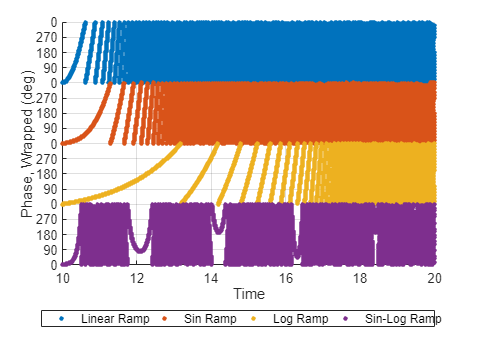

figure()
plot(testT, sin(wrapTo2Pi(linRampPhaseFcn(testT)))/2 + 3.5, ...
    '.', DisplayName='Linear Ramp', MarkerSize=10);
hold on
plot(testT, sin(wrapTo2Pi(sinRampPhaseFcn(testT)))/2 + 2.5, ...
    '.', DisplayName='Sin Ramp', MarkerSize=10);
plot(testT, sin(wrapTo2Pi(logRampPhaseFcn(testT)))/2 + 1.5, ...
    '.', DisplayName='Log Ramp', MarkerSize=10);
plot(testT, sin(wrapTo2Pi(sinLogRampPhaseFcn(testT)))/2 + 0.5, ...
    '.', DisplayName='Sin-Log Ramp', MarkerSize=10);
xlabel('Time');
ylabel('Amplitude');
ylim([0, numPlots]);
yticks((1:numPlots) - 0.5);
yticklabels(compose('%d', zeros([1, numPlots])));
legend(Location='southoutside', NumColumnsMode='auto', NumColumns=numPlots);
grid on 
box off

function Ifcn = vectorIntegral(fcn)
    function y = intHelper(xLowerB, xUpperB, fcn)
        % rescales integral to be from zero to one
        xDelta = xUpperB(:) - xLowerB(:);
        reScaledFcn = @(x, ~) fcn(x * xDelta) .* xDelta;
        [~, result] = ode45(reScaledFcn, [0, 0.5, 1], zeros(size(xDelta)), ...
            odeset('RelTol', 1e-6, 'Refine', 8));
        y = result(end, :)';
    end
Ifcn = @(xLowerB, xUpperB) intHelper(xLowerB, xUpperB, fcn);
end